Práctica 6: implementación de filtros LTI utilizando DFT  

Carga inicial de parámetros

clear; close all; clc;

% Cargar parámetros del filtro especificados en el archivo .mat
if exist('PDS_P6_3A_LE2_G4.mat', 'file')
    load('PDS_P6_3A_LE2_G4.mat');
    fprintf('Parámetros cargados:\n');
    fprintf('  M = %d (orden del filtro)\n', M);
    fprintf('  Apass = %.1f dB (atenuación en banda de paso)\n', Apass);
    fprintf('  Astop = %.1f dB (atenuación en banda de rechazo)\n', Astop);
else
    error('El archivo PDS_P6_3A_LE2_G4.mat no se encuentra en la carpeta actual.');
end

Parámetros cargados:


  M = 100 (orden del filtro)


  Apass = 0.1 dB (atenuación en banda de paso)


  Astop = 80.0 dB (atenuación en banda de rechazo)


Diseño de un filtro FIR  

a) Lectura y reproducción de la señal de audio

clear;
close all;
clc;

load("PDS_P6_3A_LE2_G4.mat");
% Lectura del archivo de audio
[x, fs] = audioread('PDS_P6_3A_LE2_G4.wav');

% Reproducción del audio (comenzar con volumen bajo)
sound(x, fs);

b) Especificación de la frecuencia de muestreo y frecuencia de corte

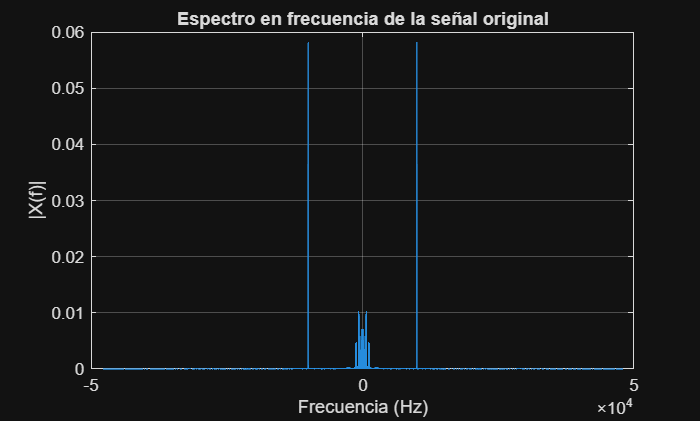

%% Obtención y representación 
N = length(x);

% FFT normalizada
X = fft(x) / N;

% Eje de frecuencias centrado
f = linspace(-fs/2, fs/2, N);

% Espectro centrado
X_shift = fftshift(abs(X));

figure;
plot(f, fftshift(abs(X)));
grid on;
xlabel('Frecuencia (Hz)');
ylabel('|X(f)|');
title('Espectro en frecuencia de la señal original');


%% Obtencion componentes espectrales de mayor frec
% Umbral para detectar picos relevantes (10% del máximo)
threshold = 0.1 * max(X_shift);

% Índices de componentes relevantes
idx = find(X_shift > threshold);

% Frecuencias correspondientes
freqs_relevantes = f(idx);

% Componente positiva de mayor frecuencia
f_pos_max = max(freqs_relevantes(freqs_relevantes > 0));

% Componente negativa de mayor frecuencia
f_neg_max = min(freqs_relevantes(freqs_relevantes < 0));

% Mostrar resultados
disp(['Componente frecuencial positiva más alta: ', num2str(f_pos_max), ' Hz']);

Componente frecuencial positiva más alta: 10001.034 Hz


disp(['Componente frecuencial negativa más alta: ', num2str(f_neg_max), ' Hz']);

Componente frecuencial negativa más alta: -10000.8298 Hz


c) Diseño del filtro FIR con fdatool

load("filtro_fir.mat");

d) Representación de la respuesta en frecuencia del filtro

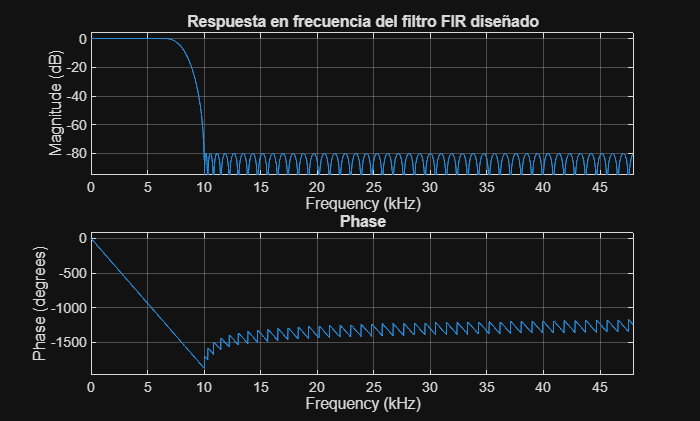

figure;
freqz(b, 1, 2048, fs);
grid on;
title('Respuesta en frecuencia del filtro FIR diseñado');

Implementación de un filtro FIR utilizando DFT  

a) Implementación del algoritmo de solape-almacenamiento

% ========== IMPLEMENTACIÓN DEL ALGORITMO DE SOLAPE-ALMACENAMIENTO ==========
% Este algoritmo filtra la señal x_n mediante convolución lineal usando FFT

% 1. Parámetros iniciales del algoritmo
L = 500;                              % Longitud de cada segmento de entrada
M_filt = length(b);                   % Orden del filtro
P = L + M_filt - 1;                   % Longitud de la DFT: P = L + M - 1

% [COMPAÑERO 1 DEBE HABER CARGADO x y fs en el Bloque 1]
% Si no está cargado, cargar aquí:
% [x, fs] = audioread('nombre_archivo.wav');

N_entrada = length(x);                % Longitud total de la señal de entrada

% 2. Preparación del filtro en el dominio de la frecuencia
% Aumentar el filtro b a longitud P con ceros
h_n = [b'; zeros(L, 1)];              % Vector columna de coeficientes padded a P
H_n = fft(h_n, P);                    % Transformada de Fourier del filtro (una sola vez)

% 3. Inicialización de variables
y = [];                               % Vector de salida final
overlap = zeros(M_filt - 1, 1);       % Solapamiento del segmento anterior

% 4. Cálculo del número de segmentos
num_segmentos = ceil(N_entrada / L);

% ========== BUCLE PRINCIPAL: PROCESAR CADA SEGMENTO ==========

for k = 1:num_segmentos
    % 4.1. Extraer segmento de entrada de longitud L
    idx_inicio = (k-1) * L + 1;
    idx_fin = min(k * L, N_entrada);
    x_seg = x(idx_inicio:idx_fin);
    
    % 4.2. Rellenar con ceros si es el último segmento y tiene menos de L muestras
    if length(x_seg) < L
        x_seg = [x_seg; zeros(L - length(x_seg), 1)];
    end
    
    % 4.3. Calcular la FFT del segmento de entrada (relleno a P)
    X_fft = fft(x_seg, P);
    
    % 4.4. Multiplicación en el dominio de la frecuencia
    % Convolución circular = Multiplicación elemento a elemento en frecuencia
    Y_fft = X_fft .* H_n;
    
    % 4.5. Transformada inversa de Fourier (vuelve al dominio del tiempo)
    y_seg_completo = ifft(Y_fft, P);
    
    % 4.6. Tomar la parte real (descartar ruido numérico imaginario)
    y_seg_completo = real(y_seg_completo);
    
    % 4.7. Solape-almacenamiento (Overlap-Add):
    % La convolución y_seg_completo tiene P = L + M - 1 puntos
    % Separamos:
    %   - Primeros (M-1) puntos: solape con el segmento anterior
    %   - Últimos L puntos: salida válida de este segmento
    
    % Sumar el solapamiento anterior a los primeros (M-1) puntos de la salida
    y_seg_completo(1:M_filt-1) = y_seg_completo(1:M_filt-1) + overlap;
    
    % 4.8. Acumular los L puntos válidos de salida
    y = [y; y_seg_completo(1:L)];
    
    % 4.9. Guardar el solapamiento (últimos M-1 puntos) para el siguiente segmento
    overlap = y_seg_completo(L+1:L+M_filt-1);
end

% 5. Descartar el exceso de muestras (si las hay por padding)
y = y(1:N_entrada);

% ========== REPRODUCCIÓN DE LA SEÑAL FILTRADA ==========
fprintf('Reproduciendo señal filtrada con algoritmo overlap-add (L=%d, P=%d)...\n', L, P);

Reproduciendo señal filtrada con algoritmo overlap-add (L=500, P=600)...


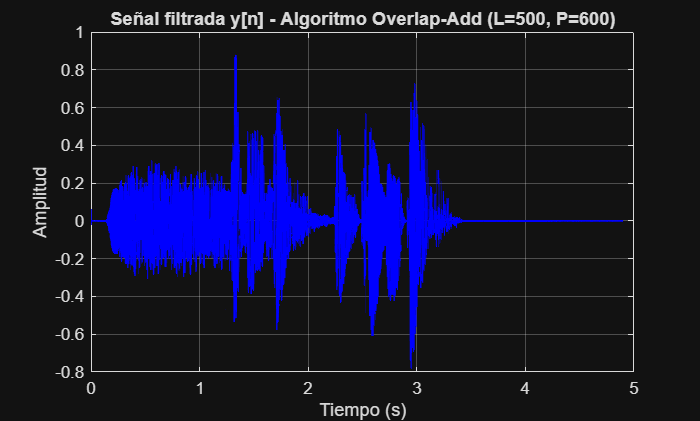

sound(y, fs);

% ========== GRÁFICA: SEÑAL FILTRADA EN EL TIEMPO ==========
figure('Name', 'Señal Filtrada - Método Overlap-Add');
t = (0:length(y)-1) / fs;
plot(t, y, 'LineWidth', 1, 'Color', 'b');
grid on;
title(sprintf('Señal filtrada y[n] - Algoritmo Overlap-Add (L=%d, P=%d)', L, P));
xlabel('Tiempo (s)');
ylabel('Amplitud');
hold off;

b) Código comentado del algoritmo

Ya se ha comentado el código. Ver .md

c) Justificación del parámetro P

% Parámetro P (longitud de la DFT)
P = L + length(b) - 1;

fprintf('\n=== PARÁMETRO P (Longitud de la DFT) ===\n');


=== PARÁMETRO P (Longitud de la DFT) ===


fprintf('L (longitud del segmento de entrada) = %d muestras\n', L);

L (longitud del segmento de entrada) = 500 muestras


fprintf('M (orden del filtro) = length(b) = %d\n', length(b));

M (orden del filtro) = length(b) = 101


fprintf('P = L + M - 1 = %d + %d - 1 = %d\n\n', L, length(b), P);

P = L + M - 1 = 500 + 101 - 1 = 600



Análisis de resultados

a) Aplicación del filtro con la función `filter` de Matlab

g = filter(b,1,x);

b) Comparación temporal: y(t) vs g(t)

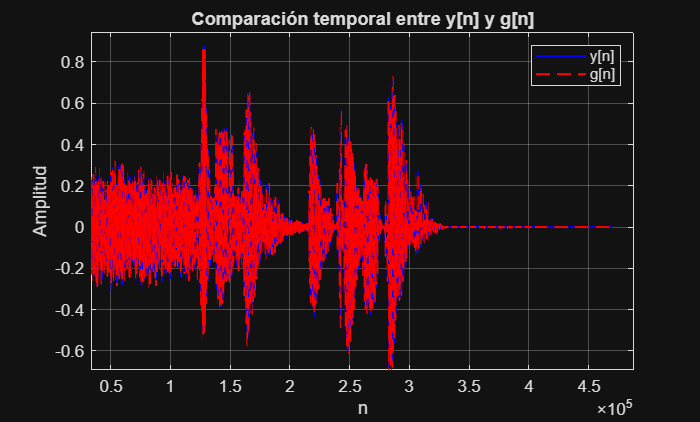

n = 0:length(y)-1;

figure;
plot(n, y, 'b', 'LineWidth', 1.2); hold on;
plot(n, g, 'r--', 'LineWidth', 1.2);
grid on;
legend('y[n]', 'g[n]');
xlabel('n');
ylabel('Amplitud');
title('Comparación temporal entre y[n] y g[n]');

c) Error cuadrático medio (MSE) entre y[n] y g[n]

% Asegurar misma longitud
N = min(length(y), length(g));

% Calcular el ECM
ECM = mean((y(1:N) - g(1:N)).^2);

% Mostrar el resultado
fprintf('El error cuadrático medio entre y[n] y g[n] es: %.6f\n', ECM);

El error cuadrático medio entre y[n] y g[n] es: 0.000000


d) Comparación del espectro en frecuencia: x[n], y[n] y g[n]

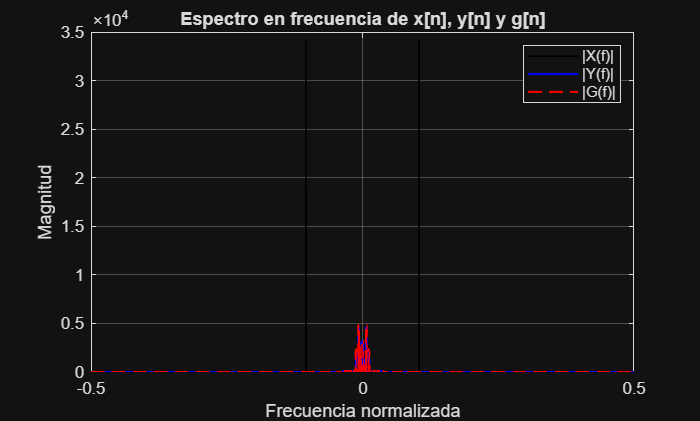

% Longitud FFT
Nfft = max([length(x), length(y), length(g)]);
Nfft = 2^nextpow2(Nfft);

% FFT centrada (correcta)
X = fftshift(fft(x, Nfft));
Y = fftshift(fft(y, Nfft));
G = fftshift(fft(g, Nfft));

% Eje de frecuencia normalizada (-0.5 a 0.5)
f = linspace(-0.5, 0.5, Nfft);

% Magnitud
Xmag = abs(X);
Ymag = abs(Y);
Gmag = abs(G);

% Representación
figure;
plot(f, Xmag, 'k', 'LineWidth', 1); hold on;
plot(f, Ymag, 'b', 'LineWidth', 1.2);
plot(f, Gmag, 'r--', 'LineWidth', 1.2);
grid on;
legend('|X(f)|', '|Y(f)|', '|G(f)|');
xlabel('Frecuencia normalizada');
ylabel('Magnitud');
title('Espectro en frecuencia de x[n], y[n] y g[n]');
xlim([-0.5 0.5]);

e) Conclusiones y análisis de resultados

Hemos podido comprobar que se ha podido fitlrar con la DFT y con el algoritmo de solape-almacenamiento, consiguiendo un ECM nulo. Ello demuestra que mediante la igualación de la convolución circular y linear (con el uso de DFTs, que normalmente no es equivalente), se logra un resultado equivalente y óptimo al del uso de un filtro FIR.